# Object Detection Using YOLO v4 Deep Learning

Este exemplo mostra como detectar objetos em imagens usando você só olhar uma vez versão 4 (YOLO v4) rede de aprendizagem profunda. Neste exemplo, você

- Configure um conjunto de dados para treinamento, validação e teste da rede de detecção de objetos YOLO v4. Você também executará o aumento de dados no conjunto de dados de treinamento para melhorar a eficiência da rede.

- Calcule caixas âncora a partir dos dados de treinamento a serem usados para treinar a rede de detecção de objetos YOLO v4.

- Crie um detector de objetos YOLO v4 usando a função e treine o detector usando a função.`yolov4ObjectDetector``trainYOLOv4ObjectDetector`

Este exemplo também fornece um detector de objetos YOLO v4 pré-treinado para usar para detectar veículos em uma imagem. A rede pré-treinada usa minúsculo-yolov4-coco como a rede de backbone e é treinada em um conjunto de dados do veículo. Para obter informações sobre a rede de detecção de objetos YOLO [v4, consulte Introdução ao YOLO v4](https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v4.html).

**Carregar conjunto de dados**

Este exemplo usa um pequeno conjunto de dados de veículo que contém 295 imagens. Muitas dessas imagens vêm dos conjuntos de dados Caltech Cars 1999 e 2001, disponíveis no site Caltech Computational Vision criado por Pietro Perona e usado com permissão. Cada imagem contém uma ou duas instâncias rotuladas de um veículo. Um pequeno conjunto de dados é útil para explorar o procedimento de treinamento YOLO v4, mas, na prática, mais imagens rotuladas são necessárias para treinar um detector robusto.

Descompacte as imagens do veículo e carregue os dados de verdade do solo do veículo..

data = load("tabelaCruz.mat");
vehicleDataset = data.T

vehicleDataset = 100×2 table
      imageFilename              cruz        
    _________________    ____________________

    "arquivo_670.jpg"    {[  195 760 115 77]}
    "arquivo_670.jpg"    {[1006 440 100 229]}
    "arquivo_671.jpg"    {[  132 777 117 89]}
    "arquivo_671.jpg"    {[1009 435 112 248]}
    "arquivo_672.jpg"    {[   58 799 125 93]}
    "arquivo_672.jpg"    {[1015 433 128 263]}
    "arquivo_673.jpg"    {[1010 432 140 285]}
    "arquivo_674.jpg"    {[ 990 426 165 310]}
    "arquivo_675.jpg"    {[ 958 424 178 335]}
    "arquivo_676.jpg"    {[ 904 428 210 352]}
    "arquivo_677.jpg"    {[ 831 431 237 337]}
    "arquivo_679.jpg"    {[ 734 439 262 398]}
    "arquivo_681.jpg"    {[ 595 436 300 425]}
    "arquivo_682.jpg"    {[ 468 443 313 444]}
    "arquivo_683.jpg"    {[ 314 452 351 459]}
    "arquivo_684.jpg"    {[ 156 465 350 458]}


Os dados do veículo são armazenados em uma tabela de duas colunas. A primeira coluna contém os caminhos do arquivo de imagem e a segunda coluna contém as caixas delimitadoras.

Exibir as primeiras linhas do conjunto de dados.

% Display first few rows of the data set.
vehicleDataset(1:4,:)

ans = 4×2 table
      imageFilename              cruz        
    _________________    ____________________

    "arquivo_670.jpg"    {[  195 760 115 77]}
    "arquivo_670.jpg"    {[1006 440 100 229]}
    "arquivo_671.jpg"    {[  132 777 117 89]}
    "arquivo_671.jpg"    {[1009 435 112 248]}


% Adicione o caminho completo à pasta de dados do veículo local.
vehicleDataset.imageFilename = fullfile(pwd,"dados\vehicleImages\",vehicleDataset.imageFilename);

Divida o conjunto de dados em conjuntos de treinamento, validação e teste. Selecione 60% dos dados para treinamento, 10% para validação e o restante para testar o detector treinado.

rng("default");
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = vehicleDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = vehicleDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = vehicleDataset(shuffledIndices(testIdx),:);

Use e crie armazenamentos de dados para carregar os dados de imagem e rótulo durante o treinamento e a avaliação.`imageDatastoreboxLabelDatastore`

imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,"cruz"));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,"cruz"));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,"cruz"));

Combine armazenamentos de dados de rótulos de imagem e caixa.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Use para detectar imagens inválidas, caixas delimitadoras ou rótulos quando o conjunto de dados contiver um ou mais dos seguintes:`validateInputData`

- Amostras com formato de imagem inválido ou valores NaN

- Caixas delimitadoras contendo zeros/valores NaN/valores Inf/vazios

- Rótulos ausentes ou não categóricos

Os valores das caixas delimitadoras devem ser inteiros positivos finitos e não devem ser NaN. A altura e a largura dos valores da caixa delimitadora devem ser positivas e estar dentro do limite da imagem.

trainingDataTbl(1:4,:)

ans = 4×2 table
                                      imageFilename                                              cruz       
    __________________________________________________________________________________    __________________

    "C:\Users\vgame\MATLAB\Projects\IC\resources\dados\vehicleImages\arquivo_4213.jpg"    {[1318 507 55 60]}
    "C:\Users\vgame\MATLAB\Projects\IC\resources\dados\vehicleImages\arquivo_1004.jpg"    {[679 385 88 119]}
    "C:\Users\vgame\MATLAB\Projects\IC\resources\dados\vehicleImages\arquivo_1014.jpg"    {[587 435 84 112]}
    "C:\Users\vgame\MATLAB\Projects\IC\resources\dados\vehicleImages\arquivo_808.jpg"     {[690 400 96 123]}


Exiba uma das imagens de treinamento e etiquetas de caixa.

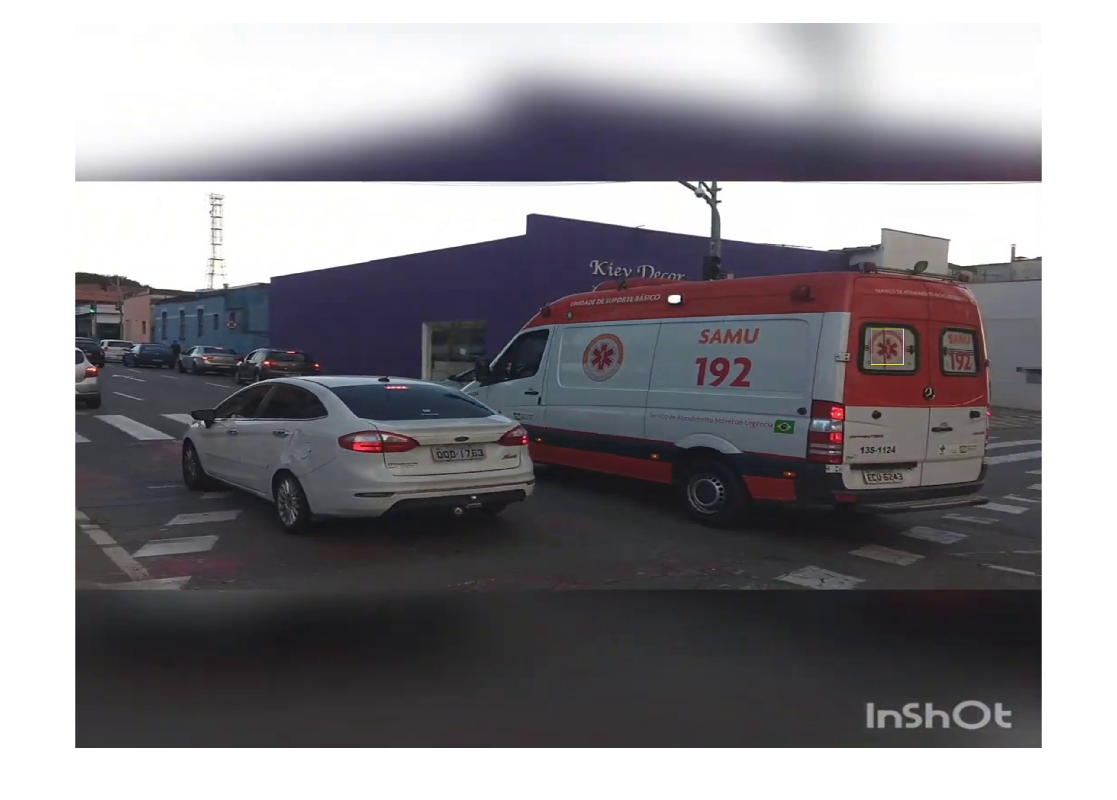

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

reset(trainingData);

## Create a YOLO v4 Object Detector Network

Especifique o tamanho de entrada de rede a ser usado para treinamento.

inputSize = [608 608 3];

Especifique o nome da classe de objeto a ser detectada.

className = "cruz";

Use a função [`estimateAnchorBoxes`](https://www.mathworks.com/help/vision/ref/estimateanchorboxes.html) para estimar caixas âncora com base no tamanho dos objetos nos dados de treinamento. Para levar em conta o redimensionamento das imagens antes do treinamento, redimensione os dados de treinamento para estimar as caixas de ancoragem. Use a função para pré-processar os dados de treinamento e, em seguida, defina o número de caixas de âncora e estime as caixas de âncora. Redimensione os dados de treinamento para o tamanho de entrada da rede usando a função auxiliar.`transform``preprocessData`

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 9;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


Especifique o argumento como as caixas âncora a serem usadas em todos os cabeçotes de detecção. As caixas de ancoragem são especificadas como uma matriz de células de `M `, onde M denota o número de cabeças de detecção. Cada cabeça de detecção consiste em uma matriz `N` que é armazenada no argumento, onde `N` é o número de âncoras a serem usadas. Especifique o para cada cabeça de detecção com base no tamanho do mapa de feição. Use âncoras maiores em escala mais baixa e âncoras menores em escala mais alta. Para fazer isso, classifique as âncoras por área, em ordem decrescente, e atribua as três primeiras à primeira cabeça de detecção e as três últimas à segunda cabeça de detecção.`anchorBoxes[x 1][ x 2]anchorsanchorBoxes`

area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");

anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)
    anchors(7:9,:)
    };

Para obter mais informações sobre como escolher caixas âncora, consulte [Estimar caixas âncora de dados de treinamento](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-from-training-data.html) (caixa™ de ferramentas de visão computacional) e [Caixas âncora para detecção de objetos](https://www.mathworks.com/help/vision/ug/anchor-boxes-for-object-detection.html).

Crie o detector de objetos YOLO v4 usando a função. especificar o nome da rede de detecção YOLO v4 pré-treinada treinada no conjunto de dados COCO. Especifique o nome da classe e as caixas de âncora estimadas.`yolov4ObjectDetector`

detector = yolov4ObjectDetector("csp-darknet53-coco",className,anchorBoxes,InputSize=inputSize);

**Especificar opções de treinamento**

Use para especificar opções de treinamento de rede. Treine o detector de objetos usando o Adam solver por 80 épocas com uma taxa de aprendizado constante de 0,001. Para obter um detector treinado com a menor perda de validação, defina como . Defina para os dados de validação e para 1000. Para validar os dados com mais frequência, você pode reduzir o que também aumenta o tempo de treinamento. Use para determinar quais recursos de hardware serão usados para treinar a rede. O valor padrão para é ", que seleciona uma GPU se ela estiver disponível e, caso contrário, seleciona a CPU. Definido para um local temporário para permitir o salvamento de detectores parcialmente treinados durante o processo de treinamento. Se o treinamento for interrompido, por exemplo, por uma queda de energia ou falha do sistema, você poderá retomar o treinamento a partir do ponto de verificação salvo. `trainingOptions``OutputNetwork``"best-validation-loss"``ValidationData``ValidationFrequency``ValidationFrequency``ExecutionEnvironment``ExecutionEnvironment``auto"``CheckpointPath` 

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=2,...
    L2Regularization=0.0005,...
    MaxEpochs=50,...
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=20,...
    ValidationFrequency=1000,...
    CheckpointPath=tempdir,...
    ValidationData=validationData,...
    ExecutionEnvironment='auto');

**Trem YOLO v4 Detector de Objetos**

Use a função para treinar o detector de objetos YOLO v4. Este exemplo é executado em uma NVIDIA™ RTX A5000 com 24 GB de memória. O treinamento dessa rede levou aproximadamente 33 minutos usando essa configuração. O tempo de treinamento varia de acordo com o hardware que você usa. Em vez de treinar a rede, você também pode usar um detector de objetos YOLO v4 pré-treinado na Computer Vision Toolbox™.`trainYOLOv4ObjectDetector`

Baixe o detector pré-treinado usando a função auxiliar. Para treinar o detector nos dados de treinamento aumentados, defina o valor como .`downloadPretrainedYOLOv4Detector``doTraining``true`

doTraining = true;
if doTraining       
    % Train the YOLO v4 detector.
    [detector,info] = trainYOLOv4ObjectDetector(trainingData,detector,options);
else
    % Load pretrained detector for the example.
    %detector = downloadPretrainedYOLOv4Detector();
end

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* cruz

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1         20         00:07:06        0.001         1876.9                     
      2         40         00:12:49        0.001         477.22                     
      2         60         00:17:47        0.001         264.66                     
      3         80         00:22:52        0.001         185.46                     
      4         100        00:27:49        0.001         145.03                     
      4         120        00:32:50        0.00

Execute o detector em uma imagem de teste.

I = imread("arquivo_8065.jpg");
[bboxes,scores,labels] = detect(detector,I);

Exiba os resultados.

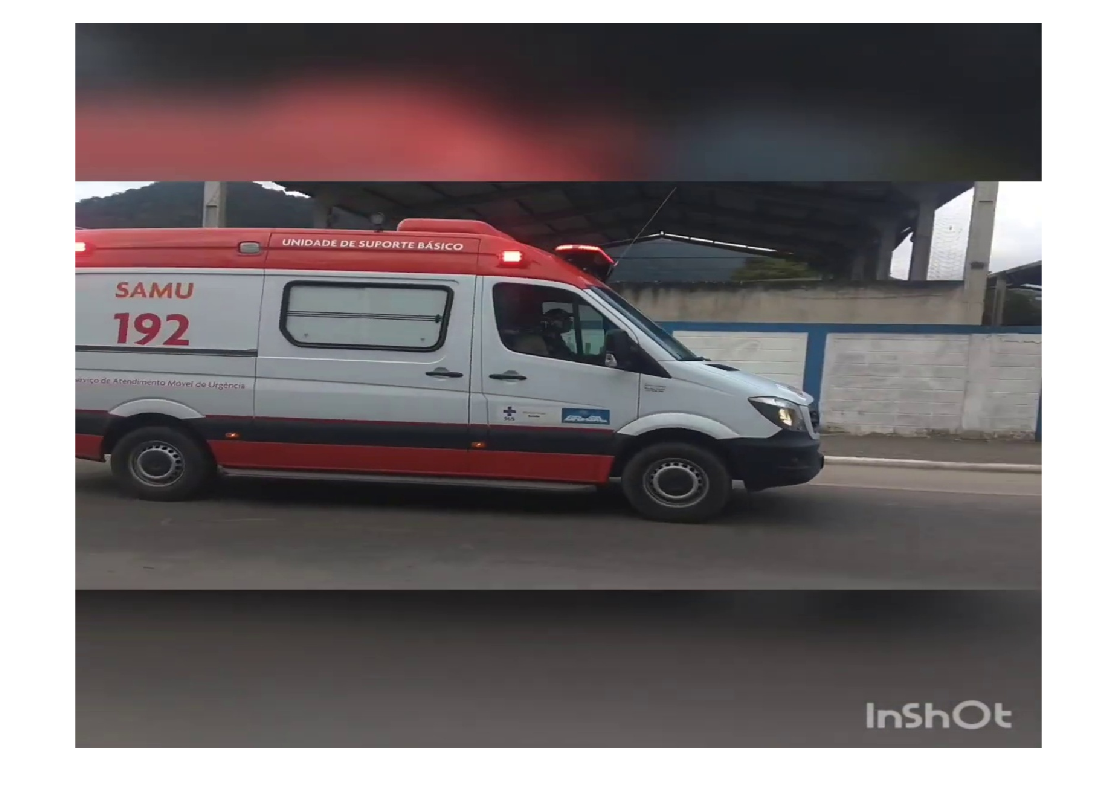

I = insertObjectAnnotation(I,"rectangle",bboxes,scores);
figure
imshow(I)

**Avalie o detector usando o conjunto de teste**

Avalie o detector de objetos treinado em um grande conjunto de imagens para medir o desempenho. O Computer Vision Toolbox™ fornece uma função de avaliação do detector de objetos ([`evaluateObjectDetection`](https://www.mathworks.com/help/vision/ref/evaluateobjectdetection.html)) para medir métricas comuns, como precisão média e taxa de erro log-média. Para este exemplo, use a métrica de precisão média para avaliar o desempenho. A precisão média fornece um único número que incorpora a capacidade do detector de fazer classificações corretas (precisão) e a capacidade do detector de encontrar todos os objetos relevantes (recall).

Execute o detector em todas as imagens de teste. Defina o limite de detecção como um valor baixo para detectar o maior número possível de objetos. Isso ajuda a avaliar a precisão do detector em toda a gama de valores de recall.

detectionResults = detect(detector,testData);

Avalie o detector de objetos usando a métrica de precisão média.

metrics = evaluateObjectDetection(detectionResults,testData);
classID = 1;
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

A curva precision-recall (PR) destaca a precisão de um detector em diferentes níveis de recall. A precisão ideal é 1 em todos os níveis de recall. O uso de mais dados pode ajudar a melhorar a precisão média, mas pode exigir mais tempo de treinamento. Plote a curva PR.

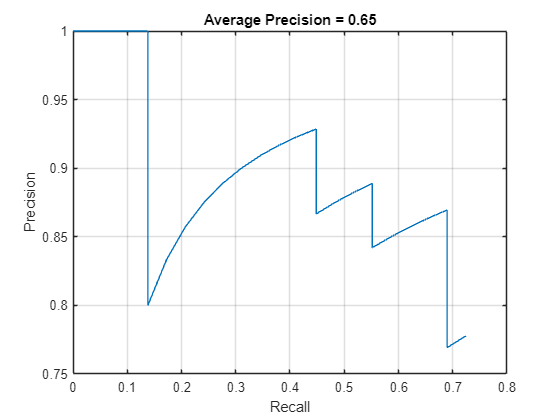

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",metrics.ClassMetrics.mAP(classID)))

*Copyright 2021 The MathWorks, Inc.*